load("Data\CFD_confined_TSR_1_1.mat")
X = flow_data(1).X;
Y = flow_data(1).Y;
theta = zeros(length(flow_data),1);
for i = 1:length(flow_data)
    theta(i) = flow_data(i).theta;
end
%thetab = flip(theta);
thetab = 365 - theta;
syms t;
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];
thet = [0:pi/32:2*pi,0]';

%k = 32
k = 25

k = 25

alpha = theta(k);
U = flow_data(k).u;
V = flow_data(k).v;
sz = length(X);
Xrot3 = zeros(sz);
Yrot3 = zeros(sz);
for j = 1:sz
    T3 = [X(:,1)';Y(:,j)'];
    XYRy2 = Ry2*T3; 
    res = subs(XYRy2,t,alpha);
    Xrot3(:,j) = res(1,:);
    Yrot3(:,j) = res(2,:);
end
foiltest = plot_foil(theta(k),1);
XYRy2 = Ry2*foiltest';
res = subs(XYRy2,t,alpha);
foiltest(:,:) = res';
%qc = 2.118*[sind(theta(k));cosd(theta(k))];
qc = 2.042*[sind(theta(k));cosd(theta(k))];
qc = Ry2*qc;
qc = subs(qc,t,-alpha);
qc = double(qc);
[Cin,Ca] = Circle2(qc,1,Xrot3,Yrot3);
[Pin,Pa] = Points2(qc,1,0.5,Xrot3,Yrot3);
qc(1) = qc(1)-1

qc =    -1.0000
    2.0420


[Rin,Ra] = Rect2(qc,0.25,2,Xrot3,Yrot3);
foiltest2 = plot_foil(theta(k),1.5);
XYRy2 = Ry2*foiltest2';
res = subs(XYRy2,t,alpha);
foiltest2(:,:) = res';

Bin = inpolygon(Xrot3,Yrot3,foiltest2(:,1),foiltest2(:,2))

Bin = 100×100 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

u3 = zeros(sz);
v3 = zeros(sz);
for i = 1:sz
    for j = 1:sz
        XYRy2 = Ry2*[U(i,j);V(i,j)];
        res = subs(XYRy2,t,alpha);
        u3(i,j) = res(1);
        v3(i,j) = res(2);
    end
end

test = [U(1,1);V(1,1)]

test =     1.0114
   -0.0935


XYRy2 = Ry2*test;
res = subs(XYRy2,t,alpha);
double(res)

ans =    -0.8381
   -0.5739


double(hypot(res(1),res(2)))

ans = 1.0158

Umean(1) = mean(u3(Cin));
Vmean(1) = mean(v3(Cin));
Umean(2) = mean(u3(Rin));
Vmean(2) = mean(v3(Rin));
Umean(3) = mean(u3(Bin));
Vmean(3) = mean(v3(Bin));

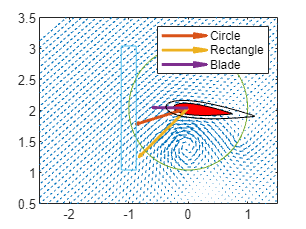

quiver(Xrot3,Yrot3,u3,v3)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
for i = 1:length(Umean)
quiver(0,2.042,Umean(i),Vmean(i),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2))
plot(Ra(:,1),Ra(:,2))
plot(foiltest2(:,1),foiltest2(:,2),'k')
hold off
legend('','','Circle','Rectangle','Blade')

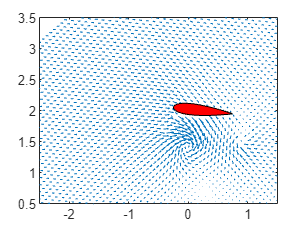

load('Data\U_11P.mat')
load('Data\V_11P.mat')
quiver(Xrot3,Yrot3,U_phase(k).u,V_phase(k).v)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
hold off

quiver(Xrot3,Yrot3,U,V)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
hold off

sum(sum((U_phase(k).u-U)))

ans = 0

max(max((U_phase(k).u-U)))

ans = 0

%rt = 0.172/2
rt = 2.042

rt = 2.0420

Uinf = 0.91

Uinf = 0.9100

lam = 1.1

lam = 1.1000

Omega = lam*Uinf/rt

Omega = 0.4902

bv = Omega*rt.*[-cosd(alpha);-sind(alpha)]

bv =     0.7703
   -0.6392


u3-bv(1)

ans =    -1.6084   -1.6080   -1.6076   -1.6071   -1.6066   -1.6061   -1.6054   -1.6046   -1.6036   -1.6023   -1.6010   -1.5996   -1.5983   -1.5967   -1.5950   -1.5929   -1.5908   -1.5886   -1.5863   -1.5840   -1.5812   -1.5784   -1.5753   -1.5722   -1.5688   -1.5655   -1.5622   -1.5587   -1.5550   -1.5510   -1.5471   -1.5435   -1.5399   -1.5361   -1.5320   -1.5281   -1.5245   -1.5214   -1.5179   -1.5139   -1.5108   -1.5081   -1.5050   -1.5024   -1.4997   -1.4968   -1.4943   -1.4923   -1.4901   -1.4880
   -1.6105   -1.6102   -1.6098   -1.6092   -1.6087   -1.6084   -1.6078   -1.6070   -1.6059   -1.6047   -1.6034   -1.6020   -1.6006   -1.5991   -1.5973   -1.5954   -1.5933   -1.5910   -1.5886   -1.5863   -1.5834   -1.5803   -1.5770   -1.5739   -1.5704   -1.5669   -1.5634   -1.5598   -1.5557   -1.5515   -1.5475   -1.5437   -1.5399   -1.5358   -1.5313   -1.5273   -1.5236   -1.5202   -1.5165   -1.5125   -1.5089   -1.5061   -1.5031   -1.5004   -1.4973   -1.4943   -1.4918   -1.4896   -1.4875   

U_phase(k).u

ans =     1.0114    1.0098    1.0082    1.0065    1.0048    1.0031    1.0012    0.9991    0.9967    0.9942    0.9916    0.9890    0.9865    0.9839    0.9811    0.9779    0.9748    0.9716    0.9684    0.9654    0.9619    0.9585    0.9548    0.9513    0.9478    0.9443    0.9410    0.9377    0.9342    0.9307    0.9274    0.9246    0.9219    0.9191    0.9160    0.9134    0.9112    0.9096    0.9076    0.9052    0.9038    0.9030    0.9018    0.9010    0.9002    0.8991    0.8986    0.8985    0.8983    0.8980
    1.0129    1.0113    1.0097    1.0078    1.0060    1.0044    1.0025    1.0003    0.9979    0.9952    0.9926    0.9900    0.9874    0.9848    0.9817    0.9785    0.9753    0.9720    0.9686    0.9656    0.9618    0.9580    0.9542    0.9506    0.9468    0.9431    0.9396    0.9361    0.9324    0.9286    0.9252    0.9222    0.9194    0.9163    0.9130    0.9104    0.9081    0.9064    0.9044    0.9021    0.8999    0.8993    0.8983    0.8976    0.8965    0.8955    0.8949    0.8948    0.8946   

U

U =     1.0114    1.0098    1.0082    1.0065    1.0048    1.0031    1.0012    0.9991    0.9967    0.9942    0.9916    0.9890    0.9865    0.9839    0.9811    0.9779    0.9748    0.9716    0.9684    0.9654    0.9619    0.9585    0.9548    0.9513    0.9478    0.9443    0.9410    0.9377    0.9342    0.9307    0.9274    0.9246    0.9219    0.9191    0.9160    0.9134    0.9112    0.9096    0.9076    0.9052    0.9038    0.9030    0.9018    0.9010    0.9002    0.8991    0.8986    0.8985    0.8983    0.8980
    1.0129    1.0113    1.0097    1.0078    1.0060    1.0044    1.0025    1.0003    0.9979    0.9952    0.9926    0.9900    0.9874    0.9848    0.9817    0.9785    0.9753    0.9720    0.9686    0.9656    0.9618    0.9580    0.9542    0.9506    0.9468    0.9431    0.9396    0.9361    0.9324    0.9286    0.9252    0.9222    0.9194    0.9163    0.9130    0.9104    0.9081    0.9064    0.9044    0.9021    0.8999    0.8993    0.8983    0.8976    0.8965    0.8955    0.8949    0.8948    0.8946    0

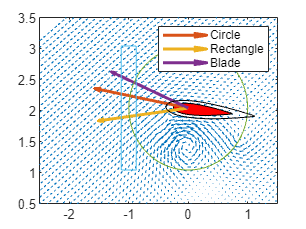

quiver(Xrot3,Yrot3,u3,v3)
xlim([-2.5 1.5])
ylim([0.5 3.5])
hold on
fill(foiltest(:,1),foiltest(:,2),'r')
for i = 1:length(Umean)
quiver(0,2.042,Umean(i)-bv(1),Vmean(i)-bv(2),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2))
plot(Ra(:,1),Ra(:,2))
plot(foiltest2(:,1),foiltest2(:,2),'k')
%plot(Pa(:,1),Pa(:,2),'*')
hold off
legend('','','Circle','Rectangle','Blade')

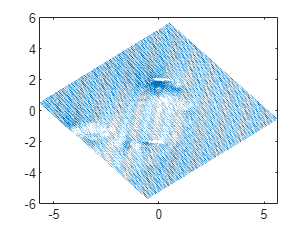

quiver(Xrot3,Yrot3,u3,v3)

Yrot4 = Yrot3-2.042;

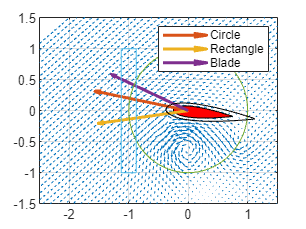

quiver(Xrot3,Yrot4,u3,v3)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
for i = 1:length(Umean)
quiver(0,0,Umean(i)-bv(1),Vmean(i)-bv(2),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2)-2.042)
plot(Ra(:,1),Ra(:,2)-2.042)
plot(foiltest2(:,1),foiltest2(:,2)-2.042,'k')
hold off
legend('','','Circle','Rectangle','Blade')
grid on

u4 = zeros(length(u3))

u4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

v4 = u4

v4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0  

for i = 1:length(Xrot3)
    for j = 1:length(Xrot3)
        x = Xrot3(i,j);
        y = Yrot3(i,j);
        rRef = hypot(x,y);
        Omega = lam*Uinf/rt;
        pv = Omega*rRef.*[-cosd(alpha);-sind(alpha)];
        u4(i,j) = u3(i,j)+pv(1);
        v4(i,j) = v3(i,j)+pv(2);
    end
end

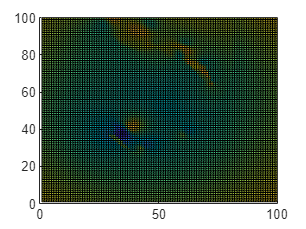

surf(u4)
view([0 90])

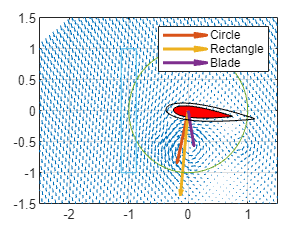

quiver(Xrot3,Yrot4,u4,v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
for i = 1:length(Umean)
quiver(0,0,Umean(i)+bv(1),Vmean(i)+bv(2),'LineWidth',2)
end
plot(Ca(:,1),Ca(:,2)-2.042)
plot(Ra(:,1),Ra(:,2)-2.042)
plot(foiltest2(:,1),foiltest2(:,2)-2.042,'k')
hold off
legend('','','Circle','Rectangle','Blade')
grid on

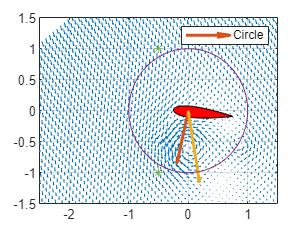

[Pin,Pa] = Points2([0;2.042],1,0.5,Xrot3,Yrot3);
quiver(Xrot3,Yrot4,u4,v4)
xlim([-2.5 1.5])
ylim([-1.5 1.5])
hold on
fill(foiltest(:,1),foiltest(:,2)-2.042,'r')
quiver(0,0,mean(u3(Cin))+bv(1),mean(v3(Cin))+bv(2),'LineWidth',2)
quiver(0,0,(mean(u3(logical(Pin)))+bv(1))/Uinf,(mean(v3(logical(Pin)))+bv(2))/Uinf,'LineWidth',2)
plot(Ca(:,1),Ca(:,2)-2.042)
plot(Pa(1,:),Pa(2,:)-2.042,'*')
hold off
legend('','','Circle')
grid on

quiver(Xrot3,Yrot4,u3,v4)

for i=[1 16 25 27 32 38 42 47]
mean(Us(i).u3(Cin))-(diff_dia_ufluid(1,i)/Uinf)
end

ans = -0.0090

ans = -0.8135

ans = -2.1639

ans = -2.3821

ans = -2.2378

ans = -1.6061

ans = -1.0125

ans = -0.4031

'v'

ans = 'v'

for i=[1 16 25 27 32 38 42 47]
mean(Us(i).v3(Cin))-(diff_dia_vfluid(1,i)/Uinf)
end

ans = -0.3479

ans = -1.0369

ans = 0.3240

ans = 0.6762

ans = 0.6762

ans = 0.7137

ans = 0.9204

ans = 0.9157

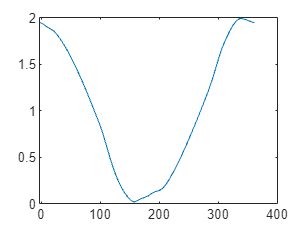

for i = 1:num
    duder9(i) = (mean(Us(i).u3(Cin)-bvs(1,:,i))+2)/2;%hypot(mean(Us(i).u3(Cin)),mean(Us(i).v3(Cin)));
end
plot(theta(1:num),duder9)

% quiver(Xrot3,Yrot3,u3,v3)
% xlim([-1 1])
% ylim([1 3])
% hold on
% fill(foiltest(:,1),foiltest(:,2),'r')
% for i = 1%:length(Umean)
% quiver(0,2.042,Umean(i),Vmean(i),'m','LineWidth',2)
% end
% hold off
% legend('','','Circle')%,'Rectangle')

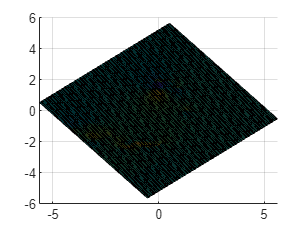

surf(Xrot3,Yrot3,u3)
view([ 0 90])

l = hypot(foiltest(:,1),foiltest(:,2))

l =     2.0892
    2.0892
    2.0892
    2.0891
    2.0890
    2.0889
    2.0888
    2.0886
    2.0884
    2.0882


[M,I] = max(l)

M = 2.1201

I = 75

foiltest(75,:)

ans =    -0.0833    2.1185


[m2,i2] = max(foiltest(:,1))

m2 = 0.7461

i2 = 1

[m3,i3] = min(foiltest(:,1))

m3 = -0.2488

i3 = 102

hypot(m2-m3,foiltest(i2,2)-foiltest(i3,2))

ans = 0.9998